
rowsToRemove = [426, 652];

% Remove the specified rows
WindData(rowsToRemove, :) = []; % This deletes the specified rows


% %Grabbing Wind speed and direction from data
 WindTheta = WindData(:,6);
 WindSpeed  = WindData(:,7);

%finding u and v components of velocity
u_wind = - WindSpeed.*(-sind(-WindTheta));
v_wind = - WindSpeed.*(cosd(WindTheta));

% Convert to datetime
dateTimeArray = datetime(WindData(:,1), WindData(:,2), WindData(:,3), WindData(:,4), WindData(:,5), 0);
disp(dateTimeArray);

   30-Jun-2024 01:00:00
   30-Jun-2024 01:10:00
   30-Jun-2024 01:20:00
   30-Jun-2024 01:30:00
   30-Jun-2024 01:40:00
   30-Jun-2024 01:50:00
   30-Jun-2024 02:00:00
   30-Jun-2024 02:10:00
   30-Jun-2024 02:20:00
   30-Jun-2024 02:30:00
   30-Jun-2024 02:40:00
   30-Jun-2024 02:50:00
   30-Jun-2024 03:00:00
   30-Jun-2024 03:10:00
   30-Jun-2024 03:20:00
   30-Jun-2024 03:30:00
   30-Jun-2024 03:40:00
   30-Jun-2024 03:50:00
   30-Jun-2024 04:00:00
   30-Jun-2024 04:10:00
   30-Jun-2024 04:20:00
   30-Jun-2024 04:30:00
   30-Jun-2024 04:40:00
   30-Jun-2024 04:50:00
   30-Jun-2024 05:00:00
   30-Jun-2024 05:10:00
   30-Jun-2024 05:20:00
   30-Jun-2024 05:30:00
   30-Jun-2024 05:40:00
   30-Jun-2024 05:50:00
   30-Jun-2024 06:00:00
   30-Jun-2024 06:10:00
   30-Jun-2024 06:20:00
   30-Jun-2024 06:30:00
   30-Jun-2024 06:40:00
   30-Jun-2024 06:50:00
   30-Jun-2024 07:00:00
   30-Jun-2024 07:10:00
   30-Jun-2024 07:20:00
   30-Jun-2024 07:30:00
   30-Jun-2024 07:40:00
   30-Jun-2024 0



%wind stress
stress = stresslp(WindSpeed,3.8); %anemometer height at 3.8m
%u_stress = stresslp(u_wind,3.8);
%v_stress = stresslp(v_wind,3.8);

u_stress = - stress.*(-sind(-WindTheta));
v_stress= -stress.*(cosd(WindTheta));
%rotate axis
[xr,yr]=rot(u_wind,v_wind,-36)

xr =    -0.2179
   -0.1465
    0.1082
   -0.2702
   -1.5493
   -0.6774
   -0.5533
   -0.7500
   -1.0418
   -0.1291


yr =    -2.4905
   -2.7962
   -3.0981
   -3.0882
   -2.9137
   -2.7168
   -2.8467
   -3.0079
   -3.0257
   -3.6977


[xr_stress, yr_stress] =rot(u_stress,v_stress,-36)

xr_stress =    -0.0009
   -0.0007
    0.0006
   -0.0014
   -0.0085
   -0.0032
   -0.0027
   -0.0039
   -0.0056
   -0.0008


yr_stress =    -0.0104
   -0.0130
   -0.0160
   -0.0159
   -0.0160
   -0.0127
   -0.0137
   -0.0155
   -0.0161
   -0.0228


%wind stress of rotated axis
%xr_stress = stresslp(xr,3.8);
%yr_stress = stresslp(yr,3.8);







%plot
figure('Units', 'Inches', 'Position', [1, 1, 12, 6]);
time = 1:length(u_wind)

time =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


plot(dateTimeArray, u_wind, 'DisplayName', 'u_{wind}');
hold on;
plot(dateTimeArray, v_wind, 'DisplayName', 'v_{wind}')

hold off;
 % marking profiles
 x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
 x_points_D = [dateTimeArray(60),dateTimeArray(81)]

x_points_D = 1×2 datetime array
   30-Jun-2024 10:50:00   30-Jun-2024 14:20:00


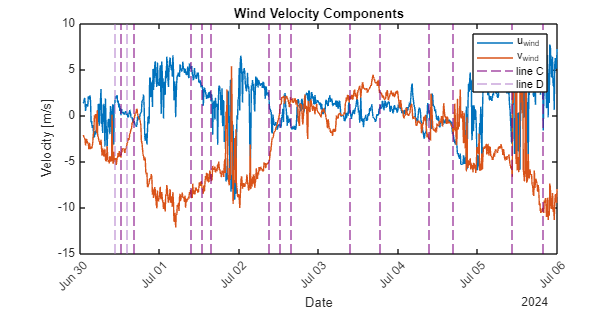

 % Create unique handles for the lines
lineC = xline(nan, 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--', 'DisplayName', 'line C'); % Dark purple
lineD = xline(nan, 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--', 'DisplayName', 'line D'); % Light purple

% % Loop through the points and draw vertical lines
 for i = 1:length(x_points_C)
     xline(x_points_C(i),'Color', [0.5, 0.0, 0.5],'LineStyle', '--'); % Dotted black lines
 end
% 
 for i = 1:length(x_points_D)
     xline(x_points_D(i),'Color', [0.7, 0.5, 0.8],'LineStyle', '--'); % Dotted black lines
  end

 xtickangle(30);


xtickangle(45);
xlabel('Date');
ylabel('Velocity [m/s]');
title('Wind Velocity Components');
legend('u_{wind}','v_{wind}','line C','line D')
hold off;


figure('Units', 'Inches', 'Position', [1, 1, 12, 6]);



% Filter the datetime array for hours 00 and 12


% Sample plot with original datetimeArray to ensure alignment
plot(dateTimeArray, WindTheta,'DisplayName', 'Wind Direction'); % Use line with markers for visibility
hold on;
 % marking profiles
 x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
 x_points_D = [dateTimeArray(60),dateTimeArray(81)]

x_points_D = 1×2 datetime array
   30-Jun-2024 10:50:00   30-Jun-2024 14:20:00


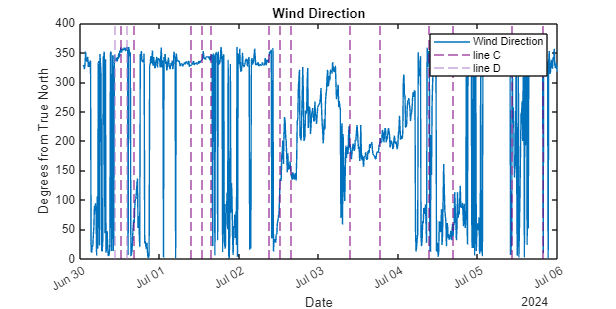

 % Create unique handles for the lines
lineC = xline(nan, 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--', 'DisplayName', 'line C'); % Dark purple
lineD = xline(nan, 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--', 'DisplayName', 'line D'); % Light purple

% % Loop through the points and draw vertical lines
 for i = 1:length(x_points_C)
     xline(x_points_C(i),'Color', [0.5, 0.0, 0.5],'LineStyle', '--'); % Dotted black lines
 end
% 
 for i = 1:length(x_points_D)
     xline(x_points_D(i),'Color', [0.7, 0.5, 0.8],'LineStyle', '--'); % Dotted black lines
  end
xtickangle(30); % Rotate labels for better readability
xlabel('Date');
ylabel('Degrees from True North');
legend('Wind Direction','line C','line D')
title('Wind Direction');
hold off;


figure('Units', 'Inches', 'Position', [1, 1, 12, 6]);
hold on;
plot(dateTimeArray, WindSpeed, 'DisplayName', 'Wind Speed');
 % marking profiles
 x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
 x_points_D = [dateTimeArray(60),dateTimeArray(81)]

x_points_D = 1×2 datetime array
   30-Jun-2024 10:50:00   30-Jun-2024 14:20:00


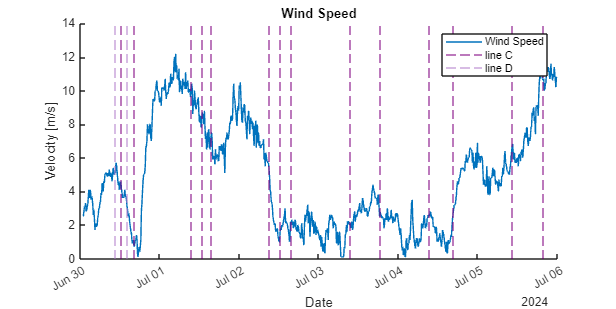

 % Create unique handles for the lines
lineC = xline(nan, 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--', 'DisplayName', 'line C'); % Dark purple
lineD = xline(nan, 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--', 'DisplayName', 'line D'); % Light purple

% % Loop through the points and draw vertical lines
 for i = 1:length(x_points_C)
     xline(x_points_C(i),'Color', [0.5, 0.0, 0.5],'LineStyle', '--'); % Dotted black lines
 end
% 
 for i = 1:length(x_points_D)
     xline(x_points_D(i),'Color', [0.7, 0.5, 0.8],'LineStyle', '--'); % Dotted black lines
  end
xtickangle(30);
xlabel('Date');
ylabel('Velocity [m/s]');
legend('Wind Speed','line C','line D')
title('Wind Speed');
hold off;

TempData = WindData(:,15);

figure('Units', 'Inches', 'Position', [1, 1, 12, 6]);



% Filter the datetime array for hours 00 and 12
validIndices = TempData <= 100;
filteredTempData = TempData(validIndices);
filteredDateTimeArray = dateTimeArray(validIndices);

figure('Units', 'Inches', 'Position', [1, 1, 12, 6]);

% Plot the filtered temperature data
plot(filteredDateTimeArray, filteredTempData, 'DisplayName', 'Wind Direction'); % Use line with markers for visibility
hold on;


 % marking profiles
 x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
 x_points_D = [dateTimeArray(60),dateTimeArray(81)]

x_points_D = 1×2 datetime array
   30-Jun-2024 10:50:00   30-Jun-2024 14:20:00


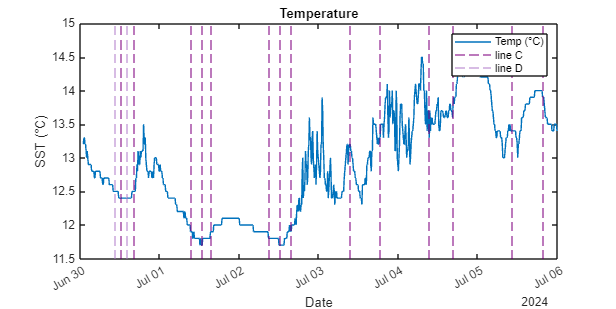

 % Create unique handles for the lines
lineC = xline(nan, 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--', 'DisplayName', 'line C'); % Dark purple
lineD = xline(nan, 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--', 'DisplayName', 'line D'); % Light purple

% % Loop through the points and draw vertical lines
 for i = 1:length(x_points_C)
     xline(x_points_C(i),'Color', [0.5, 0.0, 0.5],'LineStyle', '--'); % Dotted black lines
 end
% 
 for i = 1:length(x_points_D)
     xline(x_points_D(i),'Color', [0.7, 0.5, 0.8],'LineStyle', '--'); % Dotted black lines
  end
xtickangle(30); % Rotate labels for better readability
xlabel('Date');
ylabel('SST (°C)');
legend('Temp (°C)','line C','line D')
title('Temperature');
hold off;

% Read data
sst = ncread('jplMURSST41_8179_f371_bc30.nc', 'analysed_sst');
lat = ncread('jplMURSST41_8179_f371_bc30.nc', 'latitude');
lon = ncread('jplMURSST41_8179_f371_bc30.nc', 'longitude');
time = ncread('jplMURSST41_8179_f371_bc30.nc', 'time');

% Extract the SST data for a specific buoy location (e.g., lat=44, lon=22)
sst_bouy = sst(44, 22, :);  % Get all SST values at this location
sst_bouy = squeeze(sst_bouy);  % Remove singleton dimensions (to make it a 1D array)

% Check the size of sst_bouy
disp(length(sst_bouy));  % It should be 7, based on your earlier description

   290




% Extract the relevant time indices (e.g., 182:188)
time_indices = 182:188;  % The indices for the specific times you're interested in
sst_bouy = sst_bouy(time_indices);  % Extract the corresponding SST values

% Convert the 'time' to datetime objects and ensure proper range
dt = datetime(time, 'ConvertFrom', 'posixtime', 'TimeZone', 'UTC');
dt = dt(time_indices);  % Extract the specific times corresponding to the 7 SST values

% Make sure dateTimeArray is also in UTC (if it's not already)
dateTimeArray.TimeZone = 'UTC';
filteredDateTimeArray.TimeZone = 'UTC';
% Find the closest indices in dateTimeArray for each time in dt
 % Find the closest indices in dateTimeArray for each time in dt
% idx = zeros(size(dt));  % Pre-allocate index array
% for i = 1:length(dt)
%     [~, idx(i)] = min(abs(dateTimeArray - dt(i)));  % Find the closest index in dateTimeArray
% end

idx = [49;193;337;476;620;759;842]

idx =     49
   193
   337
   476
   620
   759
   842


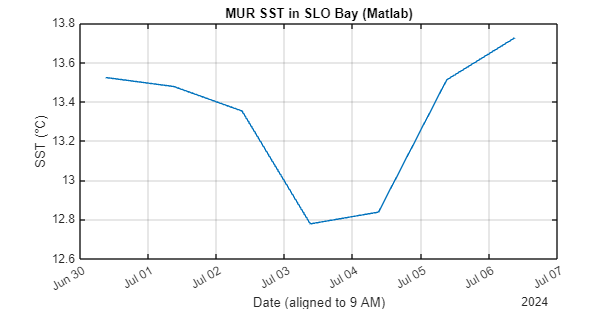

% Extract the aligned SST values based on the found indices
%alignedSST = sst_bouy(idx);  % Assuming sst_bouy corresponds to dateTimeArray

% Plot the aligned data
figure('Units', 'Inches', 'Position', [1, 1, 12, 6]);
plot(dt, sst_bouy);
xlabel('Date (aligned to 9 AM)');
ylabel('SST (°C)');
xtickangle(30);
title('MUR SST in SLO Bay (Matlab)');
grid on;

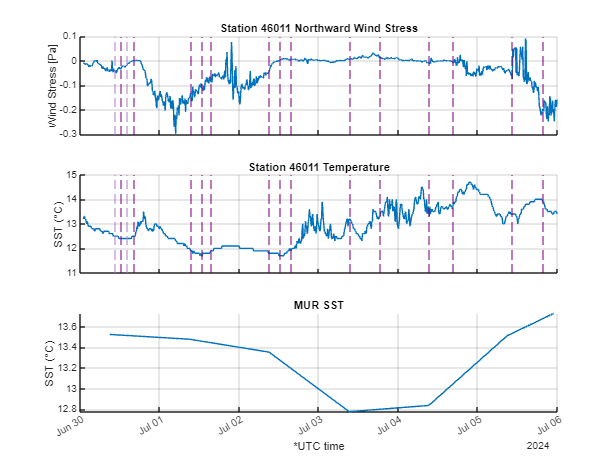

 
% Create figure with 3 subplots, vertically aligned
figure('Units', 'Inches', 'Position', [1, 1, 12, 9]);

% --------------------------------
% Plot 1: Wind Speed
subplot(3, 1, 1);  % First plot in the first position
hold on;
plot(dateTimeArray, v_stress);  % Plot Wind Speed
% Add vertical lines for profiles
x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), ...
              dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), ...
              dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
x_points_D = [dateTimeArray(60), dateTimeArray(81)];

for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('Wind Stress [Pa]');
xticklabels('')
title('Station 46011 Northward Wind Stress');
grid on;
hold off;


% --------------------------------
% Plot 2: Temperature
subplot(3, 1, 2);  % Second plot in the second position
hold on;


plot(filteredDateTimeArray, filteredTempData);  % Plot filtered temperature
% Add vertical lines for profiles
for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('SST (°C)');
xticklabels('')
title('Station 46011 Temperature');
grid on;
hold off;

% --------------------------------
% Plot 3: SST at buoy (aligned to dateTimeArray)
subplot(3, 1, 3);  % Third plot in the third position
hold on;

% Ensure the alignment for SST data (sst_bouy and idx are defined earlier)
alignedTime = filteredDateTimeArray(idx);  % Align filteredDateTimeArray using idx

plot(alignedTime, sst_bouy);  % Plot aligned SST
xlabel('*UTC time');
ylabel('SST (°C)');
xtickangle(30);
title('MUR SST');
%xticklabels(dt)
grid on;
hold off;

figure()

subplot(1,2,1);
hold on;
pointsize = 20

pointsize = 20

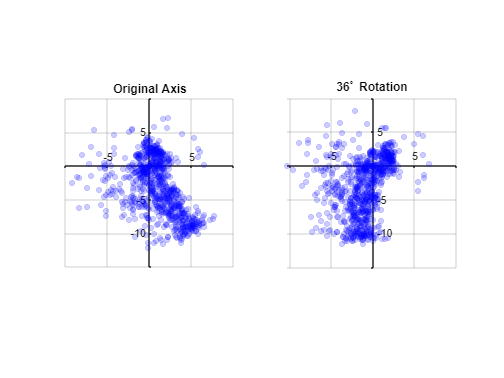

scatter(u_wind, v_wind,pointsize, 'MarkerFaceColor','b','MarkerEdgeColor','b',...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
axis equal; axis square;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
grid on
title('Original Axis')
hold off;

subplot(1,2,2);
hold on;
scatter(xr,yr,pointsize, 'MarkerFaceColor','b','MarkerEdgeColor','b',...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2)
axis equal; axis square;
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
grid on
title('36^{\circ} Rotation')
hold off;

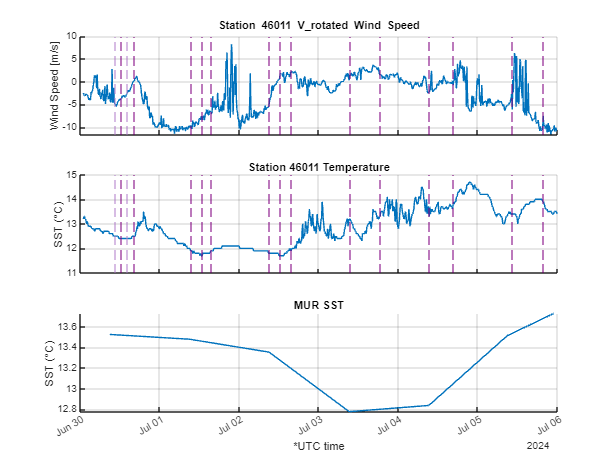

% Create figure with 3 subplots, vertically aligned
figure('Units', 'Inches', 'Position', [1, 1, 12, 9]);

% --------------------------------
% Plot 1: Wind Speed
subplot(3, 1, 1);  % First plot in the first position
hold on;
plot(dateTimeArray, yr);  % Plot Wind Speed
% Add vertical lines for profiles
x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), ...
              dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), ...
              dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
x_points_D = [dateTimeArray(60), dateTimeArray(81)];

for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('Wind Speed [m/s]');
xticklabels('')
title('Station 46011 V\_rotated Wind Speed');
grid on;
hold off;


% --------------------------------
% Plot 2: Temperature
subplot(3, 1, 2);  % Second plot in the second position
hold on;


plot(filteredDateTimeArray, filteredTempData);  % Plot filtered temperature
% Add vertical lines for profiles
for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('SST (°C)');
xticklabels('')
title('Station 46011 Temperature');
grid on;
hold off;

% --------------------------------
% Plot 3: SST at buoy (aligned to dateTimeArray)
subplot(3, 1, 3);  % Third plot in the third position
hold on;

% Ensure the alignment for SST data (sst_bouy and idx are defined earlier)
alignedTime = filteredDateTimeArray(idx);  % Align filteredDateTimeArray using idx

plot(alignedTime, sst_bouy);  % Plot aligned SST
xlabel('*UTC time');
ylabel('SST (°C)');
xtickangle(30);
title('MUR SST');
%xticklabels(dt)
grid on;
hold off;

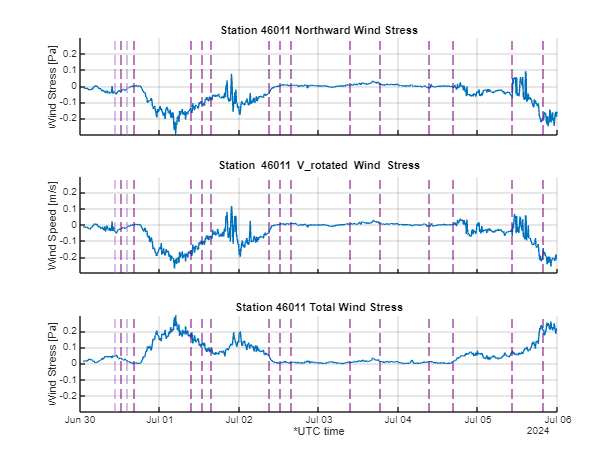

% Create figure with 3 subplots, vertically aligned
figure('Units', 'Inches', 'Position', [1, 1, 12, 9]);
min_y = min([min(v_stress), min(yr_stress), min(stress)]);
max_y = max([max(v_stress), max(yr_stress), max(stress)]);


% --------------------------------
% Plot 1: Wind Speed
subplot(3, 1, 1);  % First plot in the first position
hold on;
plot(dateTimeArray, v_stress);  % Plot Wind Speed
% Add vertical lines for profiles
x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), ...
              dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), ...
              dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
x_points_D = [dateTimeArray(60), dateTimeArray(81)];

for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('Wind Stress [Pa]');
xticklabels('')
title('Station 46011 Northward Wind Stress');
ylim([min_y, max_y]);
grid on;
hold off;


% --------------------------------
% Plot 2: Temperature
subplot(3, 1, 2);  % Second plot in the second position

hold on;
plot(dateTimeArray, yr_stress);  % Plot Wind Speed
% Add vertical lines for profiles
x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), ...
              dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), ...
              dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
x_points_D = [dateTimeArray(60), dateTimeArray(81)];

for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('Wind Speed [m/s]');
xticklabels('')
title('Station 46011 V\_rotated Wind Stress');
ylim([min_y, max_y]);
grid on;
hold off;
 
subplot(3,1,3);
hold on;
plot(dateTimeArray, stress);  % Plot Wind Speed
% Add vertical lines for profiles
x_points_C = [dateTimeArray(70), dateTimeArray(94), dateTimeArray(197), dateTimeArray(217), dateTimeArray(233), ...
              dateTimeArray(338), dateTimeArray(358), dateTimeArray(378), dateTimeArray(482), dateTimeArray(535), ...
              dateTimeArray(625), dateTimeArray(664), dateTimeArray(772), dateTimeArray(827)];
x_points_D = [dateTimeArray(60), dateTimeArray(81)];

for i = 1:length(x_points_C)
    xline(x_points_C(i), 'Color', [0.5, 0.0, 0.5], 'LineStyle', '--');  % Dark purple lines
end
for i = 1:length(x_points_D)
    xline(x_points_D(i), 'Color', [0.7, 0.5, 0.8], 'LineStyle', '--');  % Light purple lines
end
ylabel('Wind Stress [Pa]');
xlabel('*UTC time');
title('Station 46011 Total Wind Stress');
ylim([min_y, max_y]);
grid on;
hold off;